# Exercise 1

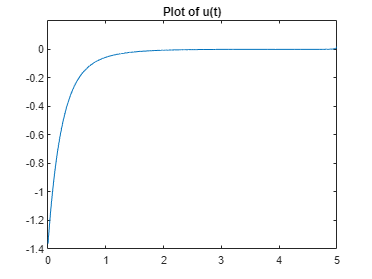

%Part 1 Continuous Finite Time
%System Dynamics
A = [0 1; -10 -7];
B = [0; 1];
%Control Setup
S = eye(2) * 20;
Q = diag([5 1]);
R = 0.25;
time_span_reverse = linspace(5, 0, 5000);
time = linspace(0, 5, 5000);
u_arr = [];
x_0 = [1;1];
%-----------------------------------------------%
%Solve LQR Problem
[t, P] = ode45(@(t, P) ricattiCT(t, P, A, B, Q, R), time_span_reverse, reshape(S, [4, 1]));
P = flip(P);
for i = 1:length(P)
    K(i,:) = -inv(R)*B'*reshape(P(i,:),[2,2]);
end
[t_new,x] = ode45(@(t_new,x) xcalc(x, A, B, K), time, x_0);
x = transpose(x);
for ii = 1:length(K)
    P_mat = [P(ii,1), P(ii,2); P(ii,3), P(ii,4)];
    u_arr(ii) = -inv(R) * transpose(B) * P_mat * x(:,ii);
end
figure(1)
plot(t_new, u_arr')
ylim([-1.4 0.2])
title("Plot of u(t)")
hold off

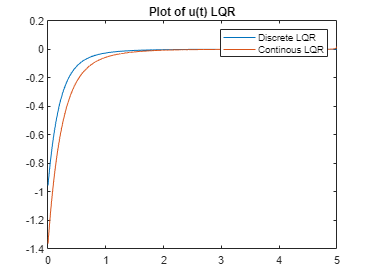

%Part 2 Discrete Time
%System Dynamics
A = [0 1; -10 -7];
B = [0; 1];
%Control Setup
N = 1000;
S = eye(2) * 20;
Q = diag([5 1]);
R = 0.25;
step = 0.005;
%-----------------------------------------------%
%Solve LQR Problem
[M, Ahat] = eig(A);
A_step = M * [exp(step * Ahat(1,1)), 0;
     0, exp(step*Ahat(2,2))]*M^-1;
B_step = A^-1*(A_step-eye(2))*B;
for ii = N:-1:1
    K(ii,:) = -(R+B_step'*S*B)^-1*B_step'*S*A_step;
    S = (A_step+B_step*K(ii,:))'*S*(A_step+B_step*K(ii,:))+Q+K(ii,:)'*R*K(ii,:);
end
x = [];
x(:,1) = [1;1];
for ii = 1:N
    u(ii) = K(ii,:)*x(:,ii);
    x(:,ii+1) = A_step*x(:,ii)+B_step*u(ii);
end
time = linspace(0, 5, 1000);
figure(2)
plot(time,u)
hold on
plot(t_new, u_arr')
legend('Discrete LQR', 'Continous LQR')
title("Plot of u(t) LQR")
xlim([0 5])
hold off

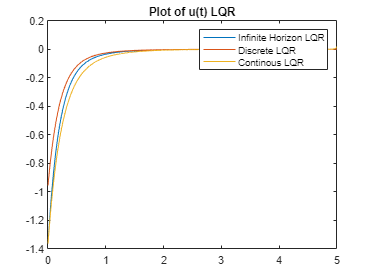

%Part 3 Infinite Horizon
%System Dynamics
A = [0 1; -10 -7];
B = [0; 1];
%Control Setup
S = eye(2) * 20;
Q = diag([5 1]);
R = 0.25;
%Solve LQR Problem
K = -lqr(A, B, Q, R);
time_arr = 0:0.01:5;
size_time = size(time_arr);
u_arr_inf = zeros(size_time);
x_arr = [1; 1];
x = lsim(A + B * K, B, [1, 0; 0, 1], 0, u_arr_inf, time_arr, x_arr);
figure(3)
plot(time_arr, (K*x')');
hold on;
plot(time,u)
hold on
plot(t_new, u_arr')
legend('Infinite Horizon LQR','Discrete LQR', 'Continous LQR')
title("Plot of u(t) LQR")
xlim([0 5])
hold off

# Exercise 2

syms F_in x x_arr delta psi x_dot y_dot psi_dot X Y s m Ca f g lf lr Iz delT

m = 1000;
f = 0.025; 
g = 9.81;
Ca = 20000; 
lf = 1.18; 
lr = 0.82; 
Iz = 3004.5; 
A =  [0, 1, 0, 0;
      0, -4*Ca/(m*x_dot), 4*Ca/m, -(2*Ca*(lf-lr))/(m*x_dot);
      0, 0, 0, 1;
      0, -(2*Ca*(lf-lr))/(Iz*x_dot), (2*Ca*(lf-lr))/Iz, (-2*Ca*(lf*lf + lr * lr))/(Iz*x_dot)];

B = [0, 2*Ca/m, 0, 2*Ca*lf/Iz];
C = eye(4);
D = [0, 0, 0, 0];
R = 25;
Q = [1, 0, 0, 0;
    0, 1, 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1]

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


function dpdt = ricattiCT(t, P, A, B, Q, R)
    P = reshape(P, size(A)); 
    dpdt = P*B*R^-1*transpose(B)*P - Q-P*A-transpose(A)*P;
    dpdt = dpdt(:);
end

function dxdt = xcalc(x, A, B, K)
    dxdt = (A-B*K(1,:))*x;
end
function S = ricattiDT(t, S, A, B, Q, R)
    S = transpose(A)*S*A - transpose(A)*S*B*(R + transpose(B)*S*B)^-1*transpose(B)*S*A+Q;
end